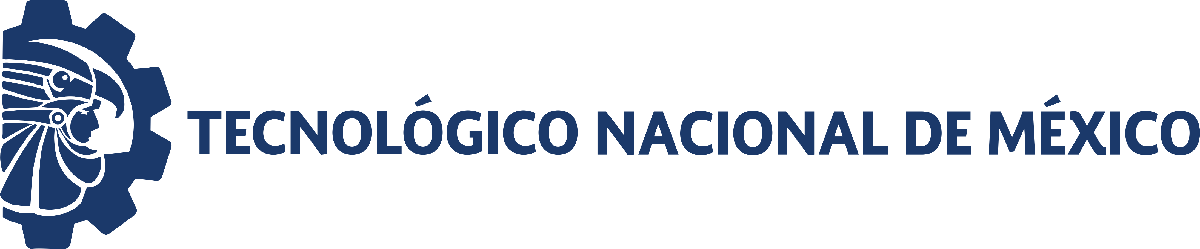                                 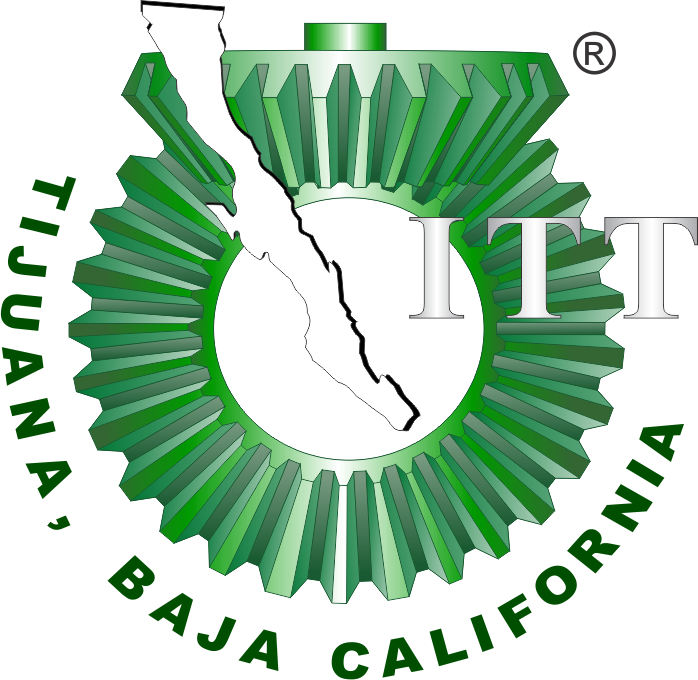

# Práctica 1: Diseño de Controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

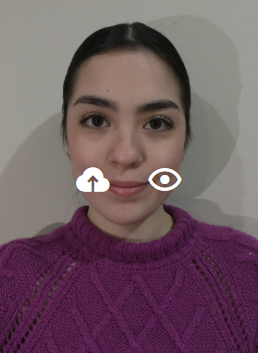

Nombre del alumno: Celia Lizette Hernandez Ruiz

Número de control: 22210415

Correo institucional: L22210415@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10'; 
file = 'P1';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';
Controlador = 'PI'; 

## Respuesta al escalón

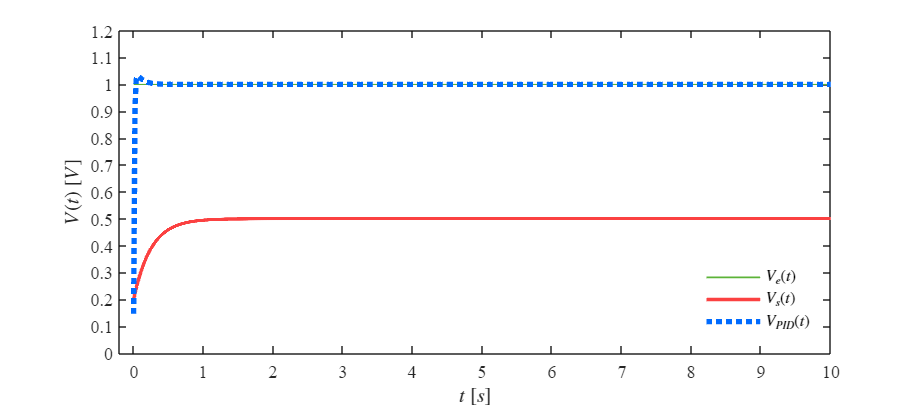

Signal = 'Escalon';
set_param('P1/S1', 'sw','1');
set_param('P1/Ve(t)', 'sw','1');
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.VPID,Controlador,Signal)

## Respuesta al impulso

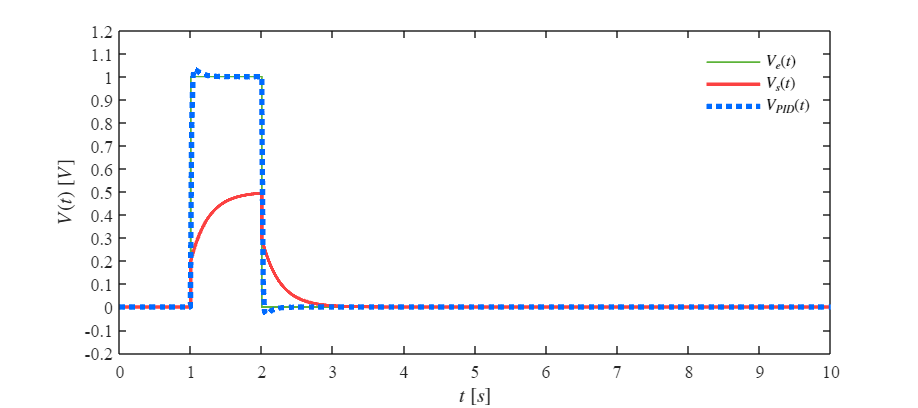

Signal = 'Impulso';
set_param('P1/S1','sw','0');
set_param('P1/Ve(t)', 'sw','1');
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.VPID,Controlador,Signal)

## Respuesta a la rampa

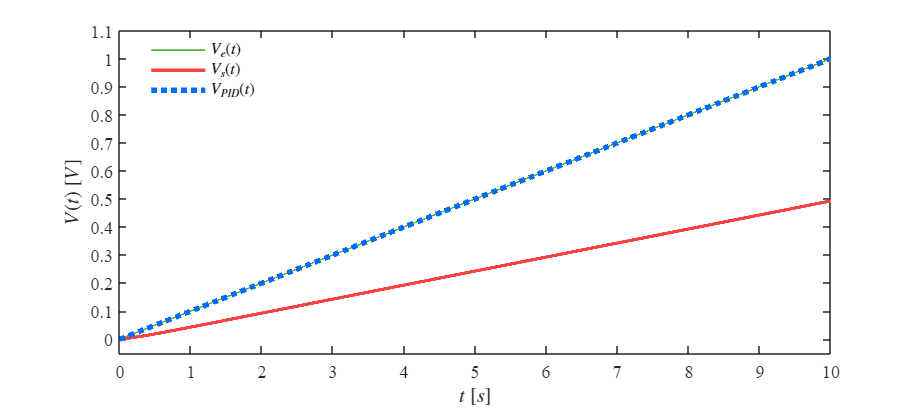

Signal = 'Rampa';
set_param('P1/S2', 'sw','1');
set_param('P1/Ve(t)', 'sw','0');
x3 = sim(file,parameters);
plotsignals(x3.t,x3.Ve,x3.Vs,x3.VPID,Controlador,Signal)

## Respuesta a la función sinusoidal

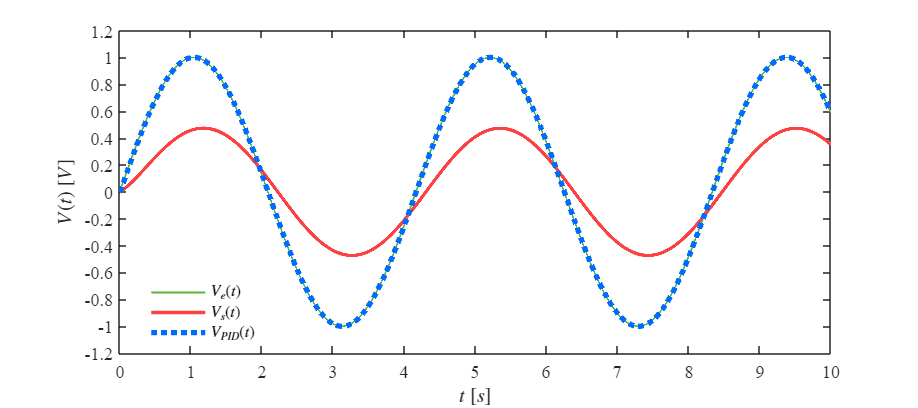

Signal = 'Sinusoidal';
set_param('P1/S2', 'sw','0');
set_param('P1/Ve(t)', 'sw','0');
x4 = sim(file,parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.VPID,Controlador,Signal)

## **Funcion : Respuerta a las señales**

function plotsignals(t,Ve,Vs,VPID,Controlador,Signal)
    set(figure(),'Color', 'w')
    set (gcf, 'Units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca,'FontName', 'Times New Roman')
    fontsize (10, 'points')
    c1 = [92/255,179/255,56/255];
    c2 = [251/255,65/255,65/255];
    c3 = [0/255,107/255,255/255];
    hold on ; grid off ; box on

    plot (t,Ve, 'LineWidth',1, 'Color',c1)
    plot (t,Vs, 'LineWidth',2, 'Color',c2)
    plot(t,VPID, ':', 'LineWidth',3, 'Color',c3)

    xlabel('$t$ $[s]$', 'Interpreter', 'latex')
    ylabel("$V(t)$ $[V]$", "Interpreter", "latex")

    L = legend ("$V_{e}(t)$", "$V_s (t)$", "$V_{PID}(t)$");
    set (L, "Interpreter", "latex", "Location", "Best", "Box", "Off")

    if Signal == "Escalon"
        xlim([-0.2,10]); xticks(0:1:10)
        ylim ([0,1.2]); yticks(0:0.1:1.2)

    elseif Signal == "Impulso"
        xlim([0,10]); xticks(0:1:10)
        ylim ([-0.2,1.2]); yticks(-0.2:0.1:1.2)

    elseif Signal == "Rampa"
        xlim([0,10]); xticks(0:1:10)
        ylim ([-0.05,1.1]); yticks(0:0.1:1.1)

    elseif Signal == "Sinusoidal"
         xlim([0,10]); xticks(0:1:10)
         ylim ([-1.2,1.2]); yticks(-1.2:0.2:1.2)

    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end
